### Setting the environment

clear;
clc;
format long;

### Constructing the matrices

mat_a = eye(10)*2 + diag(repelem(-1, 9).', -1) + diag(repelem(-1, 9).', 1) 

mat_a =      2    -1     0     0     0     0     0     0     0     0
    -1     2    -1     0     0     0     0     0     0     0
     0    -1     2    -1     0     0     0     0     0     0
     0     0    -1     2    -1     0     0     0     0     0
     0     0     0    -1     2    -1     0     0     0     0
     0     0     0     0    -1     2    -1     0     0     0
     0     0     0     0     0    -1     2    -1     0     0
     0     0     0     0     0     0    -1     2    -1     0
     0     0     0     0     0     0     0    -1     2    -1
     0     0     0     0     0     0     0     0    -1     2


### Determinants of sub-matrices

Let $d_j
$ denote the determinant of a sub-matrix of $A
$given by $A



$(1:j,1:j) for $j = 1, 2, 3 ... n$

Is it ever true that $d_n = A_{kk}d_{k-1}+d_{k-2} $ where $k = 3, 4... 10$

for ind = 3:10
    det_n = det(mat_a(1:10,1:10));
    det_n_1 = det(mat_a(1:(ind - 1),1:(ind - 1)));
    det_n_2 = det(mat_a(1:(ind - 2),1:(ind - 2)));
    a_kk = mat_a(ind, ind);
    
    lhs_comp = round(det_n, 10);
    rhs_comp = round(a_kk*det_n_1 + det_n_2, 10);
    
    if lhs_comp == rhs_comp 
        ind
        lhs_comp
        rhs_comp
    end
end

ind =      4

lhs_comp =     11

rhs_comp =     11

### Finding a new matrix G

 Extracting the 5x5 upper left matrix and 5x5 lower right matrices:

mat_ul = mat_a(1:5, 1:5)

mat_ul =      2    -1     0     0     0
    -1     2    -1     0     0
     0    -1     2    -1     0
     0     0    -1     2    -1
     0     0     0    -1     2


mat_lr = mat_a(6:end, 6:end)

mat_lr =      2    -1     0     0     0
    -1     2    -1     0     0
     0    -1     2    -1     0
     0     0    -1     2    -1
     0     0     0    -1     2


Notice that these two matrices are the same. Multiplying the two gives $G$:

mat_g = mat_ul*mat_lr

mat_g =      5    -4     1     0     0
    -4     6    -4     1     0
     1    -4     6    -4     1
     0     1    -4     6    -4
     0     0     1    -4     5


Now we need to delete some rows and colums of $G$:

mat_g([1 5], :) = [];
mat_g(:, [2 4]) = [];
mat_g

mat_g =     -4    -4     0
     1     6     1
     0    -4    -4


### Setting up matrices

Suppose $Gx = b$ where $b$ is a matrix of ones. Extract the matrices $D, L, U$from $G$:

matg_b = ones(3, 1)

matg_b =      1
     1
     1


matg_d = diag(diag(mat_g))

matg_d =     -4     0     0
     0     6     0
     0     0    -4


matg_u = triu(mat_g, 1)

matg_u =      0    -4     0
     0     0     1
     0     0     0


matg_l = tril(mat_g, -1)

matg_l =      0     0     0
     1     0     0
     0    -4     0


Contruct $H = (D + L)^{-1}$:

matg_h = inv(matg_d + matg_l)

matg_h =   -0.250000000000000                   0                   0
   0.041666666666667   0.166666666666667                   0
  -0.041666666666667  -0.166666666666667  -0.250000000000000


### Gauss-Seidel Iterative method


$$(D +L + U)x = b \Rightarrow (D + L)x = b - Ux \Rightarrow x = H(b - Ux) $$


We can iterate this from an initial guess to approximate a true value with this as below.


$$x_k = H(b - Ux_{k-1})$$


Start with $x_0 = \underline0$ and iterate the method 4 times.

x_init = zeros(3, 1);
for rep = 1:4
    if(rep == 1)
        x_prev = x_init;
    end
    x_now = matg_h*(matg_b - (matg_u*x_prev));
    x_prev = x_now;
end
gs_approx = x_now

gs_approx =   -0.606481481481481
   0.368827160493827
  -0.618827160493827


### Checking the answer with matlab

true_sol = mat_g\matg_b

true_sol =   -0.625000000000000
   0.375000000000000
  -0.625000000000000


rel_diff = (true_sol - gs_approx)./true_sol

rel_diff =    0.029629629629630
   0.016460905349794
   0.009876543209877


Therefore all answers are within 3% of the real answer and the approximation is not terrible. For more repetitions answers should converge, which they do.

### Extension - writing a function to plot convergence through time

The function that scopes the elements of g to repeat Gauss-Seidel different numbers of times can be found below. It is used here 10 times to see how the approximation converges to the true solution

ans_mat = NaN([3 10]);
for rep = 1:10
    ans_mat(:,rep) = gs_approximation(rep, matg_b, matg_u, matg_h);
end
ans_mat

ans_mat =   -0.250000000000000  -0.458333333333333  -0.569444444444444  -0.606481481481481  -0.618827160493827  -0.622942386831276  -0.624314128943759  -0.624771376314586  -0.624923792104862  -0.624974597368287
   0.208333333333333   0.319444444444444   0.356481481481481   0.368827160493827   0.372942386831276   0.374314128943759   0.374771376314586   0.374923792104862   0.374974597368287   0.374991532456096
  -0.458333333333333  -0.569444444444444  -0.606481481481481  -0.618827160493827  -0.622942386831276  -0.624314128943759  -0.624771376314586  -0.624923792104862  -0.624974597368287  -0.624991532456096


The sum of the relative difference for each set of answers can now be taken to observe how quickly the approximation converges:

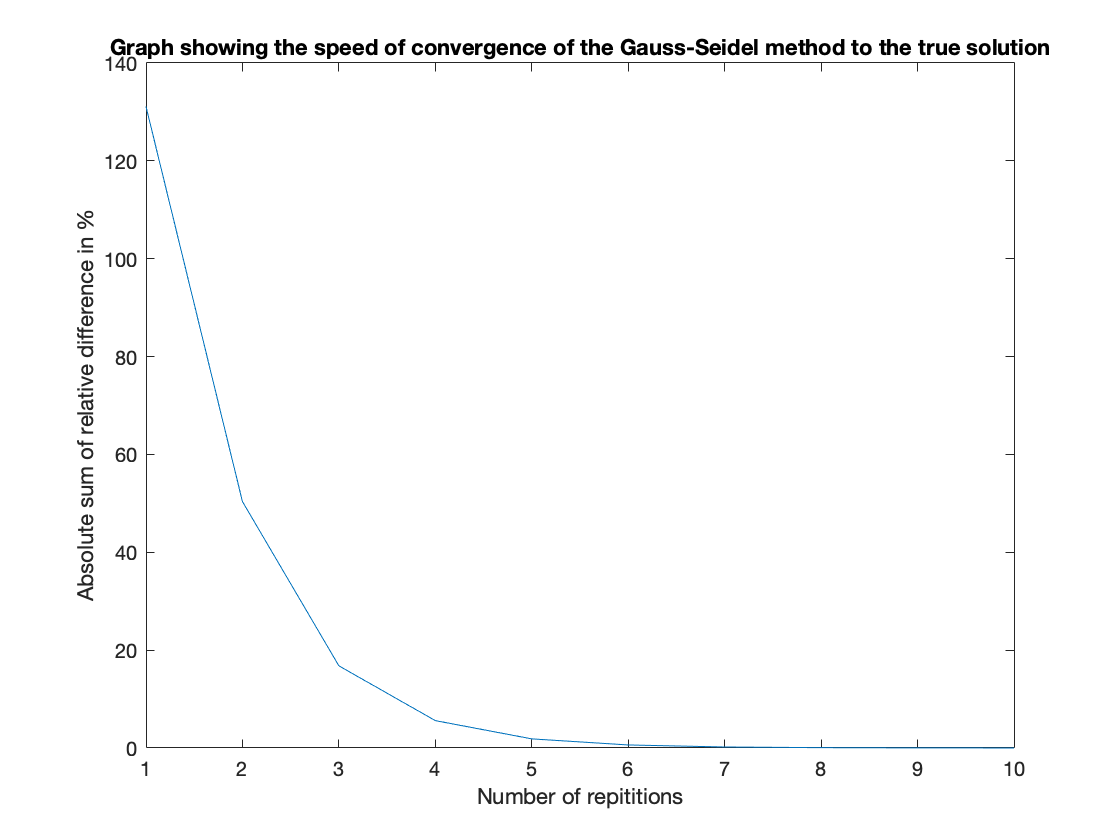

abssum_rel_diff = NaN([1 10]);
for cols = 1:10
    temp_diff = 100*(true_sol - ans_mat(:,cols))./true_sol;
    abssum_rel_diff(1, cols) = sum(abs(temp_diff));
end
plot(abssum_rel_diff)
xlabel('Number of repititions')
ylabel('Absolute sum of relative difference in %')
title('Graph showing the speed of convergence of the Gauss-Seidel method to the true solution')

function gs_app = gs_approximation(rep_times, matg_b, matg_u, matg_h)
x_init = zeros(size(matg_h, 1), 1);
for rep = 1:rep_times
    if(rep == 1)
        x_prev = x_init;
    end
    x_now = matg_h*(matg_b - (matg_u*x_prev));
    x_prev = x_now;
end
gs_app = x_now;
end